## Dynamical analysis

We plan to extend the definition provided for kinematic analysis for data required by dynamical analysis (inertias and forces).

Next we will form equations of motion for the system of unconstrained bodies.

Finally we will solve the general multibody equations of motion.

### Bodies, inertias, and coordinates

L=1;
% n=10;
m=1;
k0=100;
figure
for n=1:5
    mbs = init_mbs();
    mbs = add_body(mbs, "wall");
%     k=1000;
%     k=k_vec(n);
    k=k0*sum((1:n).^3)/n^3;
    c=1;
    for ind=1:n
        element_name="beam"+num2str(ind);
        mbs = add_body(mbs, element_name, (ind-1/2)*L/n, 0.0, 0, 'm', m/n, 'Ic', m/n * (L/n)^2 / 12);
    end
    % mbs = add_body(mbs, "beam2", 0.3, 0.0, 0, 'm', 2.0, 'Ic', 2.0 * 0.2^2 / 12);


Get mass matrix

%     M = mass_matrix(mbs)

### Joints

    % Simple joints
    mbs = add_simple_joint(mbs, "wallx", "wall", "x", 0);
    mbs = add_simple_joint(mbs, "wally", "wall", "y", 0);
    mbs = add_simple_joint(mbs, "wallangle", "wall", "fi", 0);
    %revolute joints
    mbs=add_revolute(mbs, "rev1", "wall", [0;0], "beam1", [-L/(2*n);0]);
    for ind=2:n
        elem1="beam"+num2str(ind-1);
        elem2="beam"+num2str(ind);
        joint="rev"+num2str(ind);
        mbs=add_revolute(mbs, joint, elem1, [L/(2*n);0], elem2, [-L/(2*n);0]);
    end
    % mbs=add_revolute(mbs, "revO", "wall", [0;0], "beam1", [-0.1;0]);
    % mbs=add_revolute(mbs, "rev1", "beam1", [0.1;0], "beam2", [-0.1;0]);

### Springs


    for ind=1:n
        joint="rev"+num2str(ind);
        mbs=add_rot_spring(mbs, joint, 0, k);
    end
    % mbs=add_rot_spring(mbs, "revO", 0, 100);
    % mbs=add_rot_spring(mbs, "rev1", 0, 100);

### Dampers


    for ind=1:n
        joint="rev"+num2str(ind);
        mbs=add_rot_damp(mbs, joint, c);
    end
    % mbs=add_rot_damp(mbs, "revO", 1);
    % mbs=add_rot_damp(mbs, "rev1", 1);

### Forces definition

    mbs = add_gravity(mbs, [0, -9.81]);

### Force vector

    q0 = initial_position(mbs);
    % F = forces(mbs, q0)

### Solve EOM

    dq0=q0*0;
    y0=[q0;dq0];
    opts=odeset('RelTol',1e-2,'AbsTol',1e-6);
    alpha=5;
    beta=10;
    t_span=[1 5];
    [t,y]=ode15s(@(t,y) MBS_EOM(t,y,mbs,alpha,beta),t_span,y0,opts);
    D=sin(y(:,mbs.nq))*L/(2*n)+y(:,(mbs.nq-1))-y(:,2);

Simple checking for the gravity forces

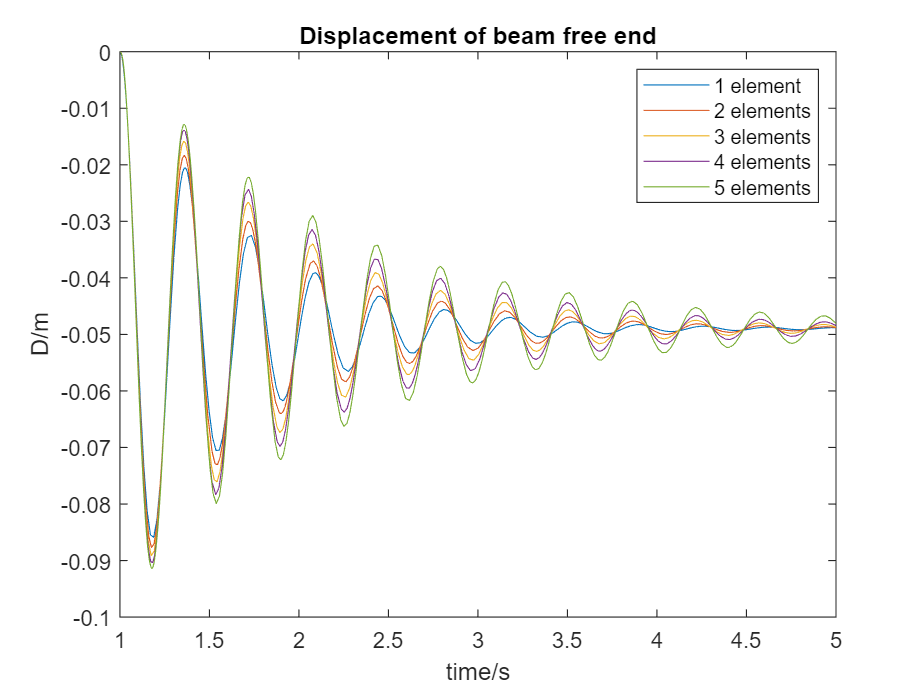

    % qpp = M\F
    % figure
    % plot(t,y(:,(mbs.nq-1)))
    % 
    % figure
    % plot(t,y(:,(mbs.nq)))
    
    plot(t,D)
    hold on
    if ind==1
        leg_arr=[num2str(ind)+" element"];
    else
        leg_arr=[leg_arr, num2str(ind)+" elements"];
    end
end
legend(leg_arr);
title("Displacement of beam free end")
xlabel("time/s")
ylabel("D/m")